% Imperial College London
% 2024-25 MRes in Medical Robotics and Instrumentation
% Coursework 01 - Task 03
% Author: Hongyu Wang

clc;
close all;
clear;

config = initConfig();
robot = initRobot(config);

% showRobotCollisionsAndFrames(robot, config.home_configuration_matlab');

### Forward Kinematics - Coppelia To MATLAB

syms th1 th2 th3 th4 th5 th6 real;
joint_angles = [th1, th2, th3, th4, th5, th6];

T_COPPELIA_FINAL = forwardKinematicsCoppelia(config.mdh, joint_angles);

% Extract position and rotation matrix
POS_COPPELIA = T_COPPELIA_FINAL(1:3, 4);  % Extract position
ROT_COPPELIA = T_COPPELIA_FINAL(1:3, 3);  % Extract rotation matrix's Z-axis (i.e., the third column)

fprintf("[LOG INFO] -- POS Size: %d x %d -- ROT Size: %d x %d", size(POS_COPPELIA, 1),size(POS_COPPELIA, 2), size(ROT_COPPELIA,1), size(ROT_COPPELIA,2));

[LOG INFO] -- POS Size: 3 x 1 -- ROT Size: 3 x 1

J_translation_coppelia = jacobian(POS_COPPELIA, joint_angles);
J_orientation_coppelia = jacobian(ROT_COPPELIA, joint_angles);

MH = double(subs(T_COPPELIA_FINAL, joint_angles, config.home_configuration_coppelia));
PH = MH(1:3, 4)';

% Waypoints in Cartesian space
P0 = [130, 0, 330] / 1000; % Initial position
P1 = [285, 0, 95] / 1000;  % First intermediate position
P2 = [150, 0, 20] / 1000;  % Second intermediate position
P3 = P0;                   % Return to initial position

% HELPER WAYPOINTS
PH0 = [PH(1, 1), 0, (P0(1, 3)+P0(1, 3))/2];
PH2 = [PH(1, 1), 0, P2(1, 3)];

WAY_POINTS = [
    PH; PH0;
    P0; PH0;
    P1;
    P2; PH2; PH0;
    P3]

WAY_POINTS =     0.1987    0.0000    0.2307
    0.1987         0    0.3300
    0.1300         0    0.3300
    0.1987         0    0.3300
    0.2850         0    0.0950
    0.1500         0    0.0200
    0.1987         0    0.0200
    0.1987         0    0.3300
    0.1300         0    0.3300


% Define the indices of key waypoints (P0, P1, P2, P3)
key_indices_idxes = [3, 5, 6, 9]; % Key waypoints in the combined waypoints

[trajectory, time_samples, total_steps, key_indices] = generateLinearTrajectory(WAY_POINTS, 3, 50, key_indices_idxes);

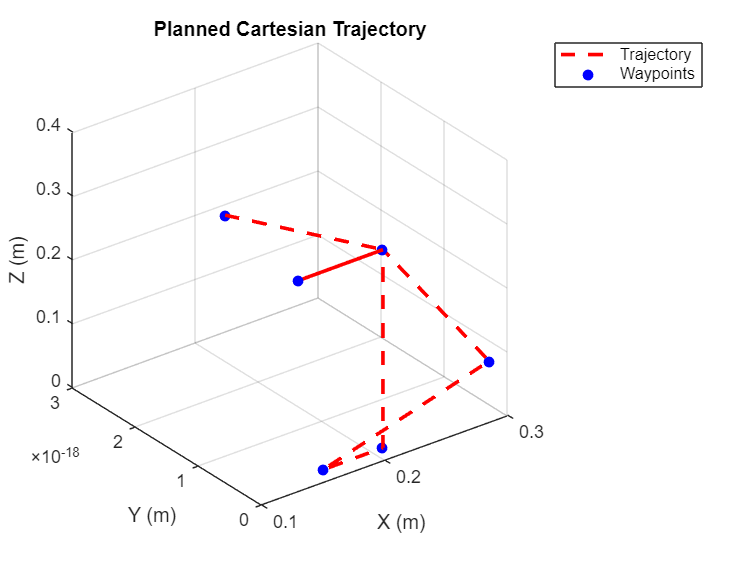

% Visualize trajectory
figure;
plot3(trajectory(:, 1), trajectory(:, 2), trajectory(:, 3), 'r--', 'LineWidth', 2);
hold on;
scatter3(WAY_POINTS(:, 1), WAY_POINTS(:, 2), WAY_POINTS(:, 3), 'bo', 'filled'); % Waypoints
% xlim([-0.4 0.4]); ylim([-0.1 0.1]); zlim([0 0.4]);
xlabel('X (m)'); ylabel('Y (m)'); zlabel('Z (m)');
title('Planned Cartesian Trajectory');
grid on;
legend('Trajectory', 'Waypoints');
hold off;

## Inverse Kinematics Solution

### Target Rotation

ROT_SAGITTAL = [0;1;0];

joint_trajectory = inverseKinematiceCoppelia(trajectory,time_samples, ...
    joint_angles,...
    config.home_configuration_coppelia,POS_COPPELIA, ...
    ROT_COPPELIA,J_translation_coppelia, J_orientation_coppelia, ...
    config.joint_angle_limits_coppelia, config.joint_velocity_limits, ...
    ROT_SAGITTAL, ...
    500, 1e-8, 0.01, 0.8);

[LOG INFO] -- Step 002 - Iteration 001: Cumulative Update Exceeded Threshold.
[LOG INFO] -- Step 003 - Iteration 001: Cumulative Update Exceeded Threshold.
[LOG INFO] -- Step 004 - Iteration 001: Cumulative Update Exceeded Threshold.
[LOG INFO] -- Step 005 - Iteration 001: Cumulative Update Exceeded Threshold.
[LOG INFO] -- Step 006 - Iteration 001: Cumulative Update Exceeded Threshold.
[LOG INFO] -- Step 007 - Iteration 001: Cumulative Update Exceeded Threshold.
[LOG INFO] -- Step 008 - Iteration 001: Cumulative Update Exceeded Threshold.
[LOG INFO] -- Step 009 - Iteration 001: Cumulative Update Exceeded Threshold.
[LOG INFO] -- Step 010 - Iteration 001: Cumulative Update Exceeded Threshold.
[LOG INFO] -- Step 011 - Iteration 007: Coveraged Successfully.
[LOG INFO] -- Step 012 - Iteration 007: Coveraged Successfully.
[LOG INFO] -- Step 013 - Iteration 007: Coveraged Successfully.
[LOG INFO] -- Step 014 - Iteration 007: Coveraged Successfully.
[LOG INFO] -- Step 015 - Iteration 007: Co

validateAngles(joint_trajectory, config.joint_angle_limits_coppelia);

[LOG INFO] -- Validate Angles...
[LOG INFO] -- All joint angles are within limits.


key_points = joint_trajectory(key_indices,:);
for key = 1:size(key_points, 1)
    T = double(subs(T_COPPELIA_FINAL, joint_angles, key_points(key,:)));
    disp(T(1:3,4)');
end

    0.1300    0.0000    0.3300

    0.2850   -0.0000    0.0950

    0.1500   -0.0000    0.0200

    0.1300    0.0000    0.3300



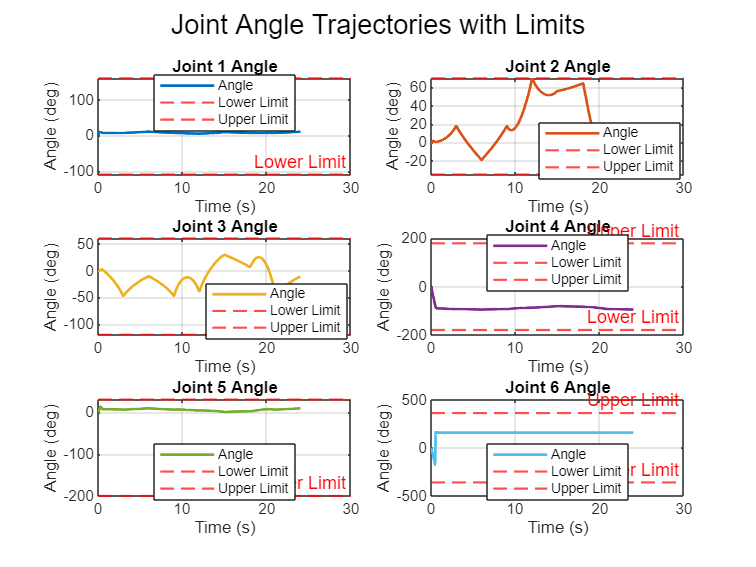

showJointAngleInTrajectory(joint_trajectory, config.joint_angle_limits_coppelia, time_samples);

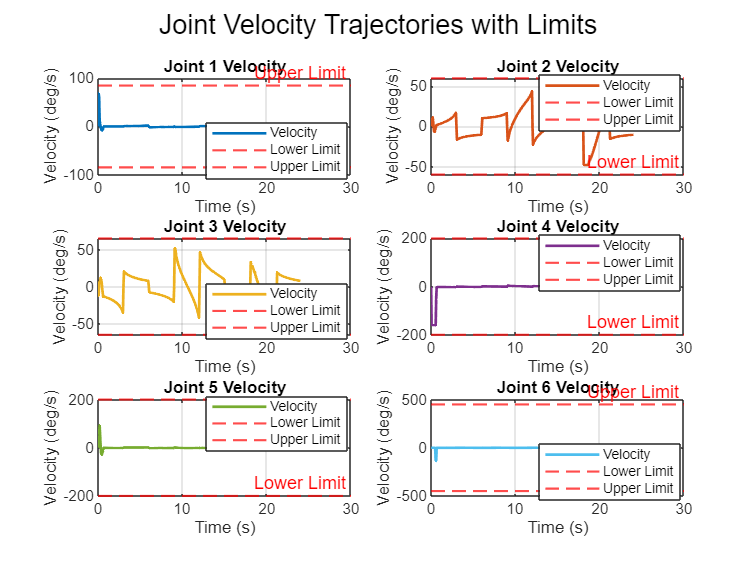

% Calculate joint velocities (numerical derivative of joint angles)
joint_velocity = diff(joint_trajectory) / (time_samples(2) - time_samples(1));  % Velocity = Δθ / Δt
joint_velocity_0 = zeros(1,6);
% Normalize the velocity differences to avoid jumps
for i = 1:size(joint_velocity, 1)
    joint_velocity(i, :) = mod(joint_velocity(i, :) + pi, 2 * pi) - pi;
end
joint_velocity = [joint_velocity_0; joint_velocity];

showJointVelocityInTrajectory(joint_velocity, config.joint_velocity_limits, time_samples);

% Real end-effector trajectory in MATLAB
ee_positions_matlab = zeros(total_steps, 3);
for k = 1:total_steps
    POS_K = double(subs(POS_COPPELIA, joint_angles, joint_trajectory(k, :))); % Compute position for each step
    ee_positions_matlab(k, :) = POS_K;
end

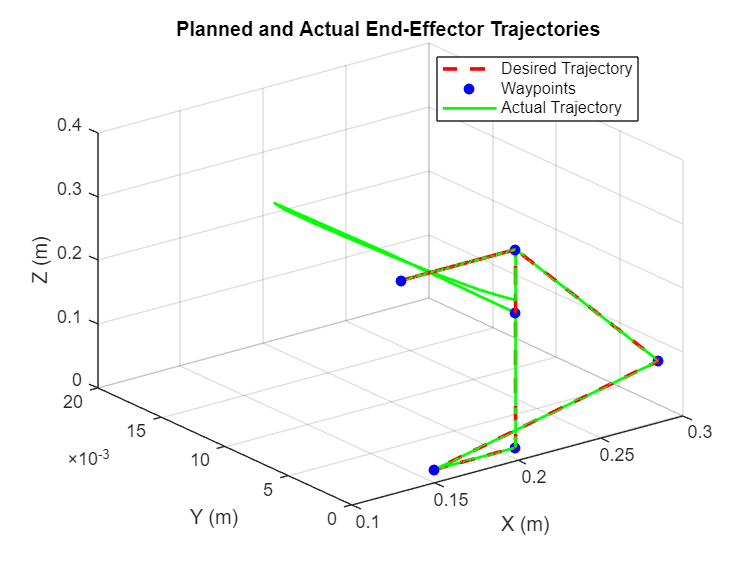

figure;
plot3(trajectory(:, 1), trajectory(:, 2), trajectory(:, 3), 'r--', 'LineWidth', 2);
hold on;
% Plot waypoints as blue circles
scatter3(WAY_POINTS(:, 1), WAY_POINTS(:, 2), WAY_POINTS(:, 3), 'bo', 'filled');
% Plot the actual end-effector trajectory in green
plot3(ee_positions_matlab(:, 1), ee_positions_matlab(:, 2), ee_positions_matlab(:, 3), 'g', 'LineWidth', 1.5);
% Labels and title
xlabel('X (m)');
ylabel('Y (m)');
zlabel('Z (m)');
title('Planned and Actual End-Effector Trajectories ');
% Set axis limits (optional, can be adjusted as needed)
% Add legend for the trajectories and waypoints
legend('Desired Trajectory', 'Waypoints', 'Actual Trajectory', 'Location', 'Best');

% Display grid
grid on;
hold off;

[LOG INFO] -- ERROR INITIAL: [0.0000, 0.0000, 0.0000] 
[LOG INFO] -- ERROR AVG: 0.0005 m
[LOG INFO] -- ERROR STD: 0.0025 m
[LOG INFO] -- ERROR MAX: 0.0193 m
[LOG INFO] -- ERROR MIN: 0.0000 m


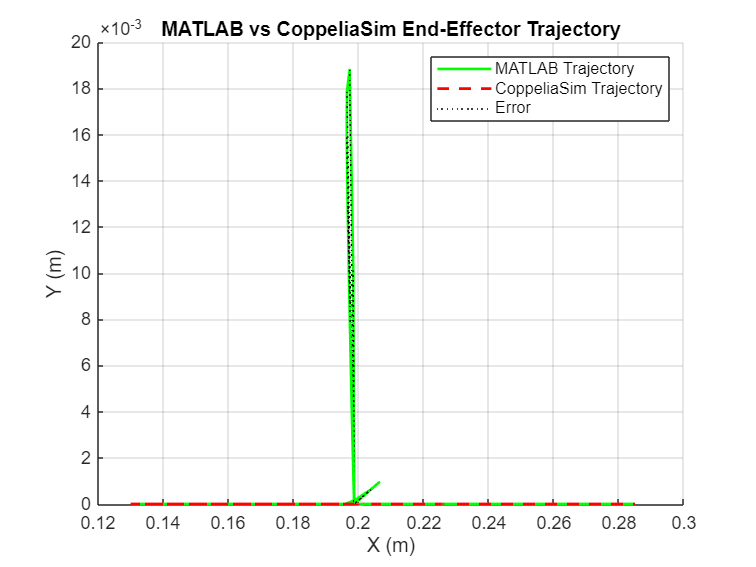

evaluateTrajectoryCoppeliaAndMATLAB(trajectory,ee_positions_matlab);

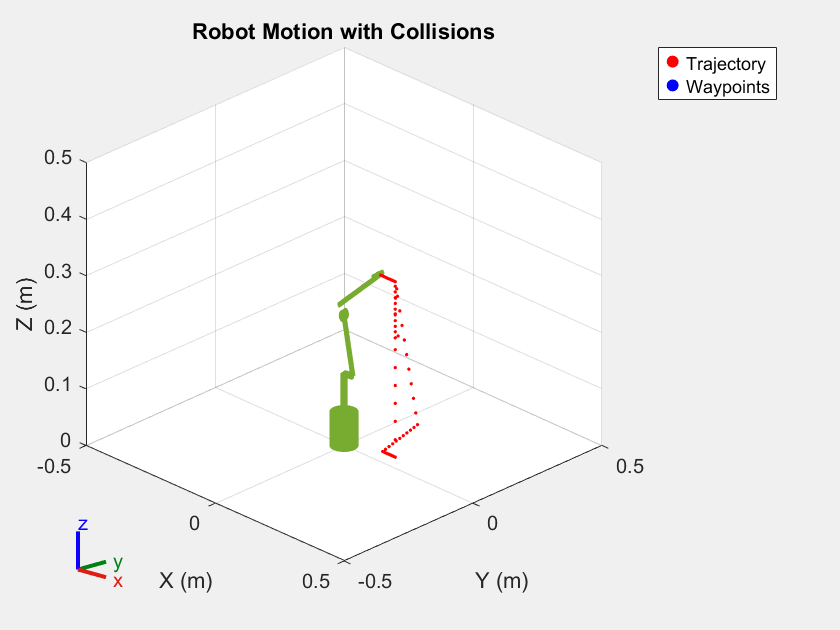

[LOG INFO] -- Simulation complete.


joint_trajectory_matlab = joint_trajectory + (config.home_configuration_matlab - config.home_configuration_coppelia);
simulateRobotMATLAB(robot, joint_trajectory_matlab,key_points,'collision', 5, true);

writematrix(joint_trajectory, 'Datas/task03_angles.csv');
writematrix(time_samples, 'Datas/task03_times.csv');

## CoppeliaSim Using ZeroMQ

HOST = '127.0.0.1'; % CoppeliaSim IP
PORT = 23000;       % Port CoppeliaSim ZeroMQ is listening on

checkCoppeliaSimConnection(HOST, PORT, 5);

[LOG INFO] -- CoppeliaSim Can be Connected
[LOG INFO] -- CoppeliaSim IP Address 127.0.0.1


% Initialize Remote API Client
simClient = RemoteAPIClient();

% Define joint names and end-effector name
jointNames = {'/Mirobot/joint1', '/Mirobot/joint2', '/Mirobot/joint3', ...
              '/Mirobot/joint4', '/Mirobot/joint5', '/Mirobot/joint6'};
eeName = '/Mirobot/Tip';

% Simulate robot in CoppeliaSim
ee_positions_coppelia = simulateRobotCoppeliaSim(joint_trajectory, time_samples, simClient, jointNames, eeName);

[LOG INFO] -- Connecting to CoppeliaSim...
[LOG INFO] -- Simulation started successfully.
[LOG INFO] -- Executing trajectory and recording end-effector positions...
[LOG INFO] -- Simulation stopped.
[LOG INFO] -- End-effector positions recorded.


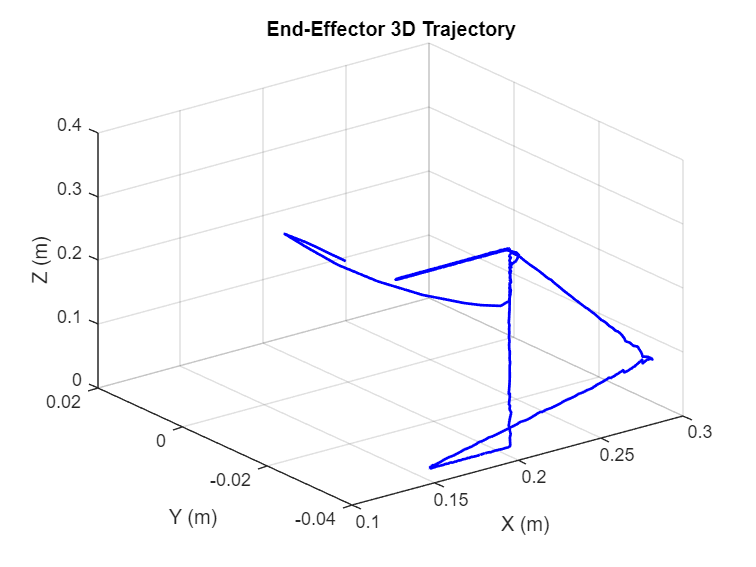

% Plot the 3D trajectory of the end-effector
figure;
plot3(ee_positions_coppelia(:, 1), ee_positions_coppelia(:, 2), ee_positions_coppelia(:, 3), 'b-', 'LineWidth', 1.5);
xlabel('X (m)');
ylabel('Y (m)');
zlabel('Z (m)');
title('End-Effector 3D Trajectory');
grid on;

## Compare MATLAB and CoppeliaSim

% Calculate the initial offset (CoppeliaSim - MATLAB)
initial_offset = ee_positions_coppelia(1, :) - ee_positions_matlab(1, :);

% Correct MATLAB trajectory using the offset
ee_positions_coppelia_corrected = ee_positions_coppelia - initial_offset;

% Log the offset information
disp('[LOG INFO] -- Initial offset applied to CoppeliaSim trajectory:');

[LOG INFO] -- Initial offset applied to CoppeliaSim trajectory:


disp(initial_offset);

   -0.0004    0.0000   -0.0407



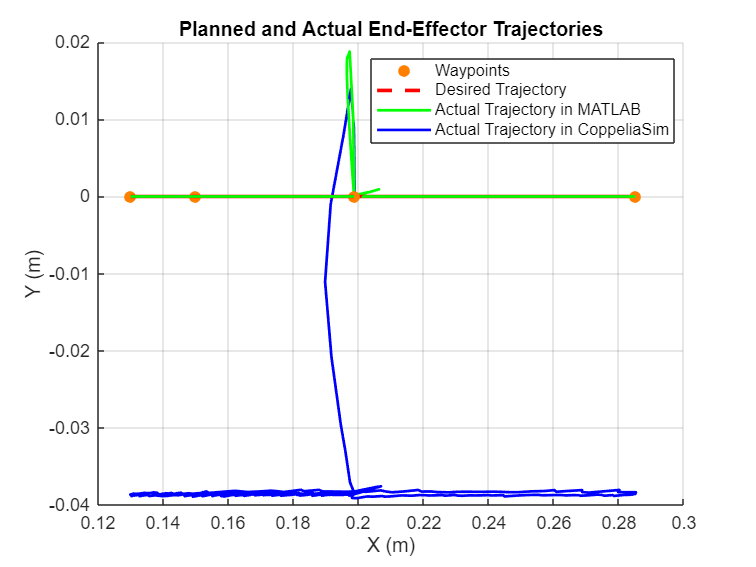

% Plot the trajectories and error vectors
figure;
hold on;
scatter3(WAY_POINTS(:, 1), WAY_POINTS(:, 2), WAY_POINTS(:, 3), 'o', 'MarkerFaceColor', [1, 0.5, 0], 'MarkerEdgeColor', [1, 0.5, 0]);
plot3(trajectory(:, 1), trajectory(:, 2), trajectory(:, 3), 'r--', 'LineWidth', 2);
plot3(ee_positions_matlab(:, 1), ee_positions_matlab(:, 2), ee_positions_matlab(:, 3), 'g-', 'LineWidth', 1.5);
plot3(ee_positions_coppelia_corrected(:, 1), ee_positions_coppelia_corrected(:, 2), ee_positions_coppelia_corrected(:, 3), 'b-', 'LineWidth', 1.5);
% Labels and title
xlabel('X (m)');
ylabel('Y (m)');
zlabel('Z (m)');
title('Planned and Actual End-Effector Trajectories');

legend('Waypoints','Desired Trajectory', 'Actual Trajectory in MATLAB', 'Actual Trajectory in CoppeliaSim', 'Location', 'Best');

% Display grid
grid on;
hold off;